# Reproduce Heeger and Simoncelli figure 5 - 8

## load parameters

pars   = shPars;
mtpref = pars.mtPopulationVelocities;

## moving dots stimulus

% mkDots
stimSz = [50 50 20];
dotDir = pi;
dotSpd = 2;
dots   = mkDots(stimSz, dotDir, dotSpd);
mfft_tuned = [];

% flipBook(dots);
[pop, ind] = shModel(dots, pars, 'mtPattern');
mtrsp = reshape(pop, [ind(2, 2), ind(2, 3), ind(2, 4), size(pop, 2)]);
rsp = squeeze(mean(mean(mean(mtrsp, 3), 2)));

## Visualize

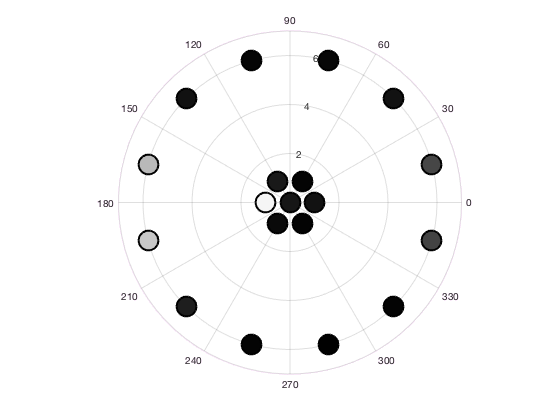

rsp = min(rsp, 1);
figure (1), clf
for k = 1 : 19
    polarplot(mtpref(k, 1), mtpref(k, 2), 'o', 'markersize', 20, 'markerfacecolor',...
        rsp(k).*ones(1, 3), 'markeredgecolor','k'),
    hold on
end

## drifting sinusoidal grating

% mkSin
stimSz  = [100, 100, 30];
stimDir = pi*3/4;
stimSf  = 0.1;
stimTf  = 0.1;
sin = mkSin(stimSz, stimDir, stimSf, stimTf);

[pop, ind] = shModel(sin, pars, 'mtPattern');
mtrsp = reshape(pop, [ind(2, 2), ind(2, 3), ind(2, 4), size(pop, 2)]);
rsp = squeeze(mean(mean(mean(mtrsp, 3), 2)));

## visualize

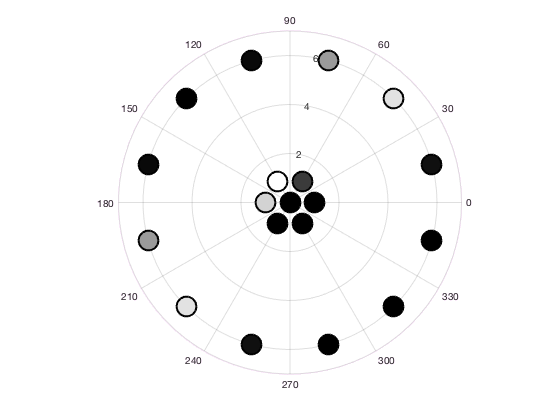


rsp = min(rsp, 1);

figure (2), clf
for k = 1 : 19
    polarplot(mtpref(k, 1), mtpref(k, 2), 'o', 'markersize', 20, 'markerfacecolor',...
        rsp(k).*ones(1, 3), 'markeredgecolor', 'k'),
    hold on
end

## plaid stimulus composed of two drifting sinusoidal gratings

% mkPlaid

## transparent motion stimulus

% mkGlass?

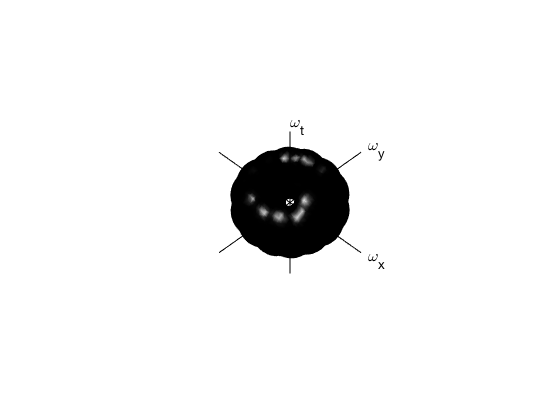

% make a time series 
[pop, ind] = shModel(dots, pars, 'v1Simple');
[f, f1] = shShowV1NeuronSpectrum(pars, pars.v1PopulationDirections(1 : 14, :));